# BarTrace

Example using BarTrace

Videos were taken at Grit City in the Bronx where I train (IG @concretejunglegritsc). Randy Triunfel (IG @thebarbellmasochist) is a competitive weightlifter and my coach. I didn't include all the video data here given it's size. The videos were all taken at the gym with either Randy or me, so the model wasn't trained with much variety.

The location of the plate is detected using a CNN with the final layers replaced by a YOLO network. I labeled data for training using image processing and imfindcircle. The image processing wasn't always correct and slow. But it sufficed for training. The resulting neural network is both more accurate and fast.

## Getting Started

Import video

vid = liftVid("DaveShort.mp4");

Find plate in each frame and draw in circle

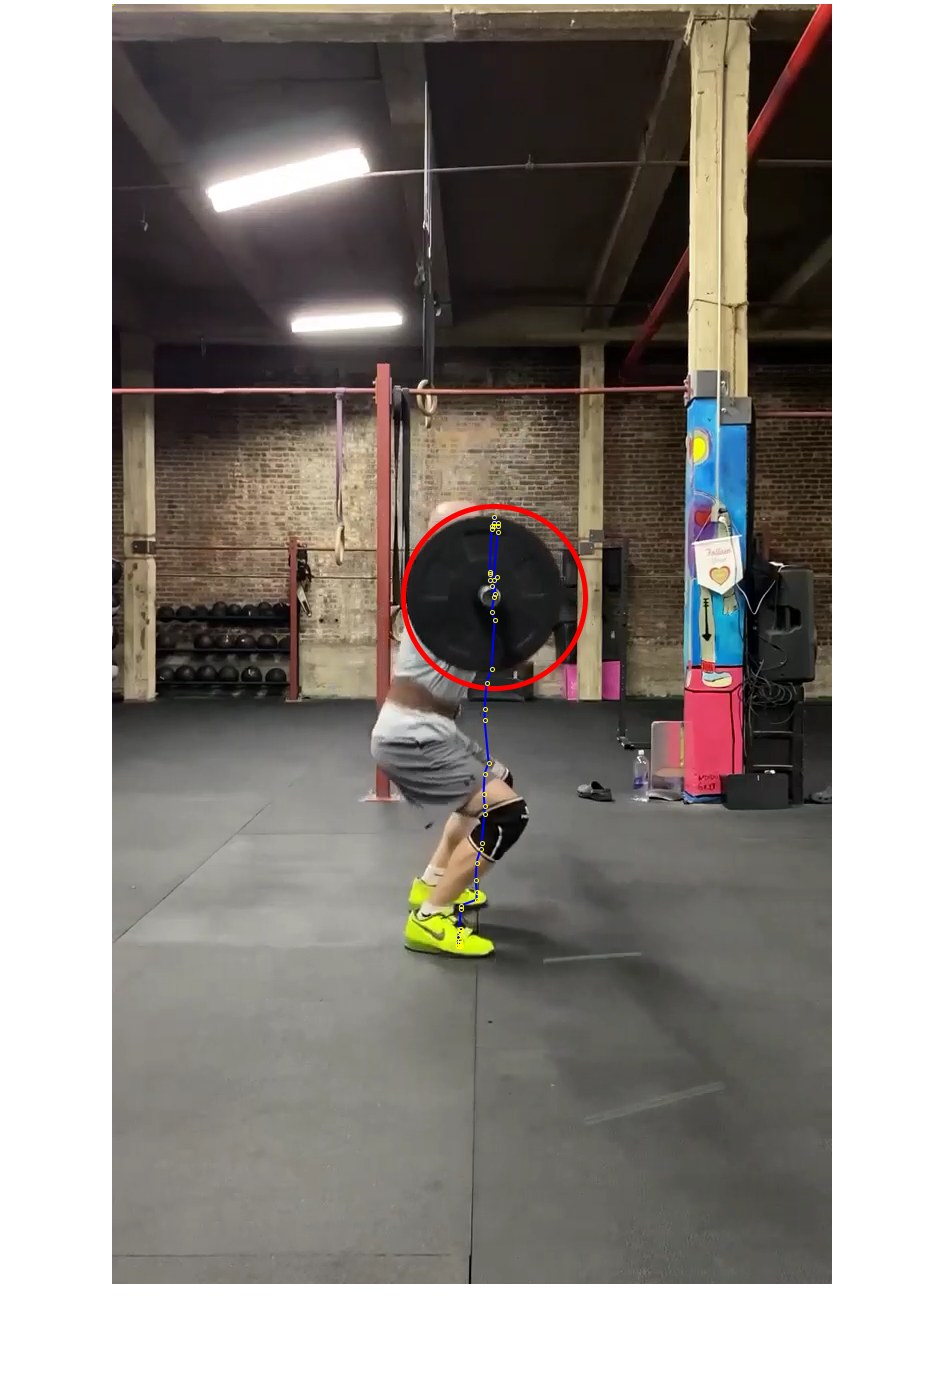

for n = 1:54
    frame = vid.processNextFrame;
end
imshow(frame)

Show all frames

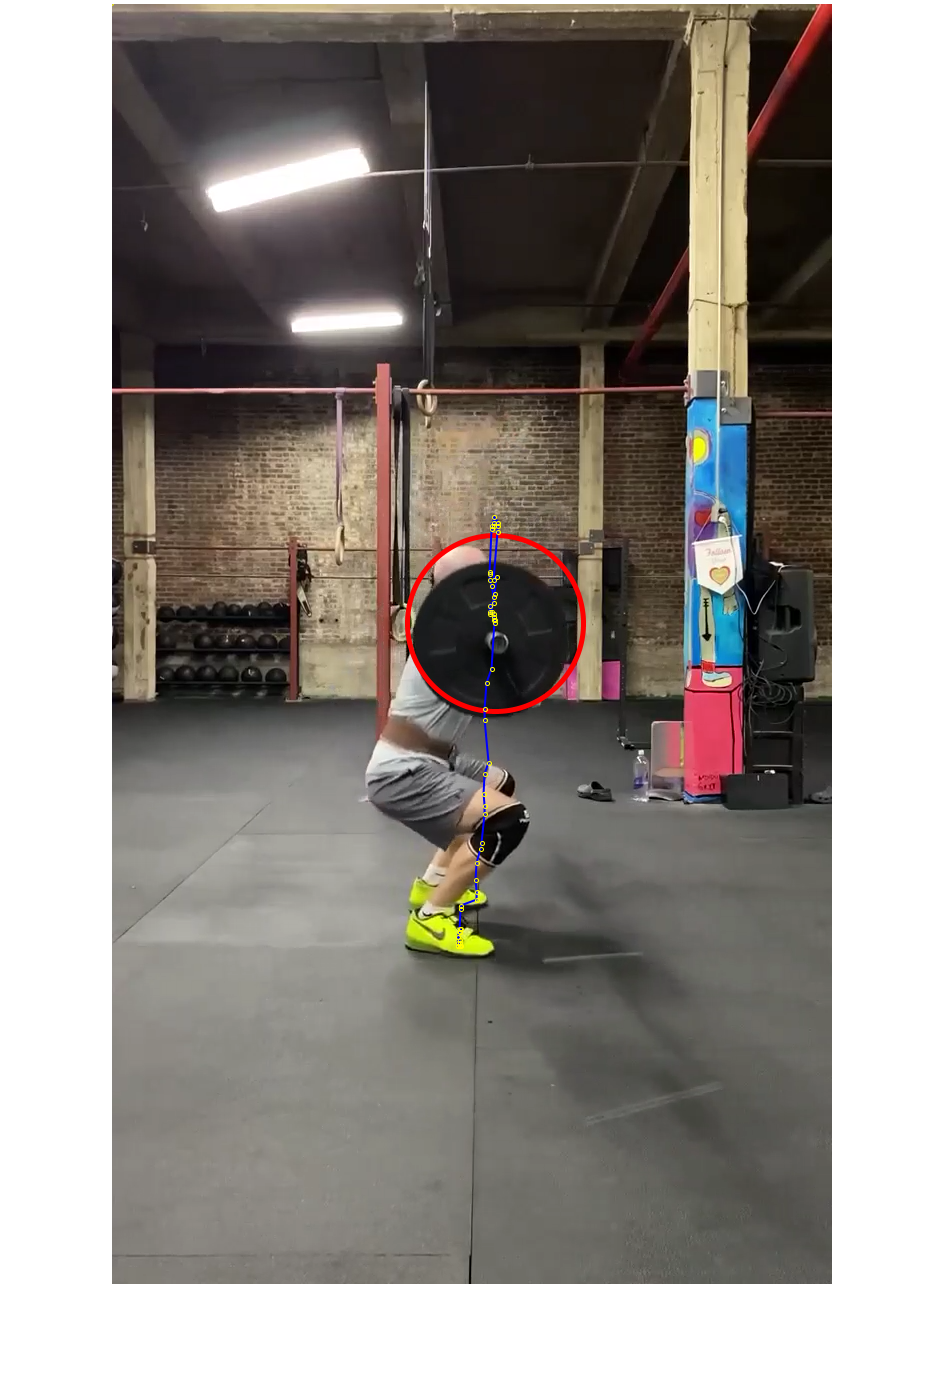

vid = liftVid("DaveShort.mp4");
vid.tracePlate(true,false,"Result1")

Save annotated video

vid = liftVid("DaveShort.mp4");
vid.tracePlate(true,true,"Result1")

## Analyze the second pull

edit("Analyze2ndPull.mlx")

## Details

liftVid finds the barbell plate in each frame and traces it's path. Yellow markers at each frame help gauge barbell speed. Videos were all shot on an iPhone 11 at 30 fps. The model was only trained with black plates on a red and black background.